[d,f] = smoothForceDisplacementData(CPosition_Rig_Def,CForce_Rig_Def)

d =    55.2600
   55.2800
   55.6500
   55.6700
   55.6900
   55.7100
   55.7300
   55.7400
   55.7600
   55.7800


f = 1.0e+04 *

    0.0498
    0.0490
    0.0481
    0.0492
    0.0490
    0.0490
    0.0494
    0.0494
    0.0494
    0.0483


mask = d>60

mask = 420×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


f=f(mask)

f = 1.0e+04 *

    0.0910
    0.0874
    0.1052
    0.0917
    0.0801
    0.2039
    0.1399
    0.1547
    0.1487
    0.1427


d=d(mask)

d =    60.0200
   60.0400
   60.0600
   60.0800
   60.1000
   60.1200
   60.1400
   60.1500
   60.1700
   60.1900


d=d-60.01

d =     0.0100
    0.0300
    0.0500
    0.0700
    0.0900
    0.1100
    0.1300
    0.1400
    0.1600
    0.1800


figure
hold on
plot(f,d,'.','Color','k')

linearFit = fittype({'x'}); 
quadraticFit = fittype({'x^2','x'});


[Lin_Rig_fit, Lin_gof_Rig] = fit(f,d,linearFit)

Lin_Rig_fit =      Linear model:
     Lin_Rig_fit(x) = a*x
     Coefficients (with 95% confidence bounds):
       a =   0.0001143  (0.0001126, 0.000116)

Lin_gof_Rig = struct with fields:
           sse: 8.1542
       rsquare: 0.9593
           dfe: 188
    adjrsquare: 0.9593
          rmse: 0.2083


RMSE_linear_mm = Lin_gof_Rig.rmse;

[Quad_Rig_Fit, Quad_gof_Rig] = fit(f,d,quadraticFit)

Quad_Rig_Fit =      Linear model:
     Quad_Rig_Fit(x) = a*x^2 + b*x
     Coefficients (with 95% confidence bounds):
       a =  -1.538e-09  (-1.637e-09, -1.44e-09)
       b =    0.000153  (0.0001504, 0.0001556)

Quad_gof_Rig = struct with fields:
           sse: 1.3508
       rsquare: 0.9933
           dfe: 187
    adjrsquare: 0.9932
          rmse: 0.0850


RMSE_quad_mm = Quad_gof_Rig.rmse;

if RMSE_quad_mm <RMSE_linear_mm
U = 2*RMSE_quad_mm
fit_data= feval(Quad_Rig_Fit,f)

%Plot Model
plot(f,fit_data,'Color','b')

%Plot Bounds
plot(f,fit_data+U,'--','Color','r')
plot(f,fit_data-U,'--','Color','r')

else
    U=2*RMSE_linear_mm
    fit_data = feval(Lin_Rig_fit,f)

    %plot Model
    plot(f,fit_data)

   %Plot Bounds
plot(f,fit_data+U)
plot(f,fit_data+U)
end

U = 0.1700

fit_data =     0.1379
    0.1325
    0.1592
    0.1390
    0.1216
    0.3055
    0.2110
    0.2330
    0.2241
    0.2152


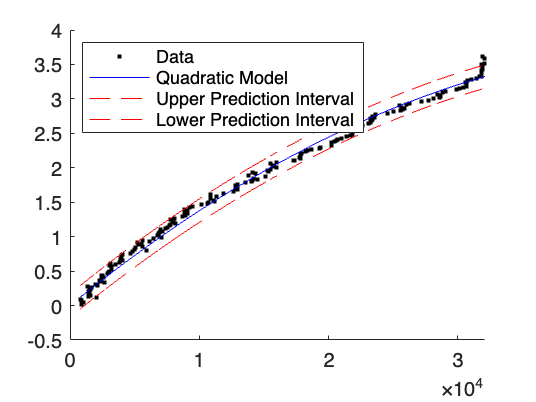

legend('Data','Quadratic Model','Upper Prediction Interval','Lower Prediction Interval','Location','northwest')